# Elliptical Natural Motion Trajectories

## For circular relative motion

## Inputs

theta_1 = pi/2;%1.58;
theta_2 = 1.58;
b = -6;

## Trajectory Calculation

nu = linspace(0, 2 * pi, 100);

c = b / sin(theta_1) * sqrt(tan(theta_2) ^ 2 + 4 * cos(theta_1) ^ 2);

psi = nu - atan(2 * cos(theta_1) / tan(theta_2));

X_0 = [b * sin(nu); 2 * b * cos(nu); c * sin(psi)];

## Plot

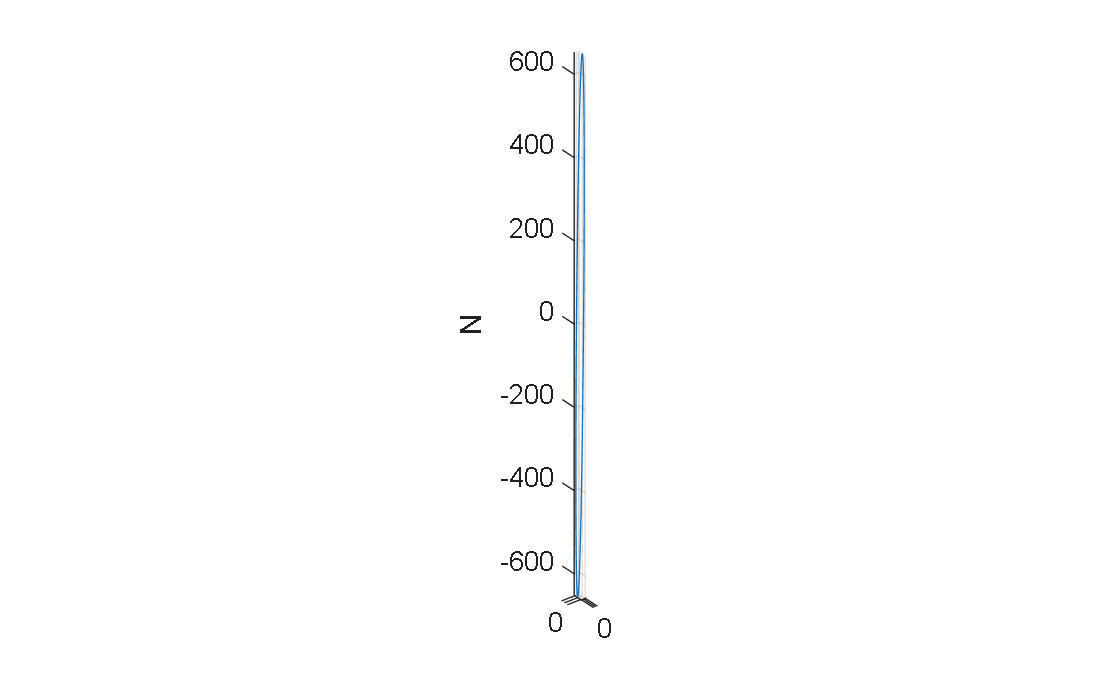

plot3(X_0(1, :), X_0(2, :), X_0(3, :))
grid on
axis equal
xlabel("R")
ylabel("Theta")
zlabel("N")

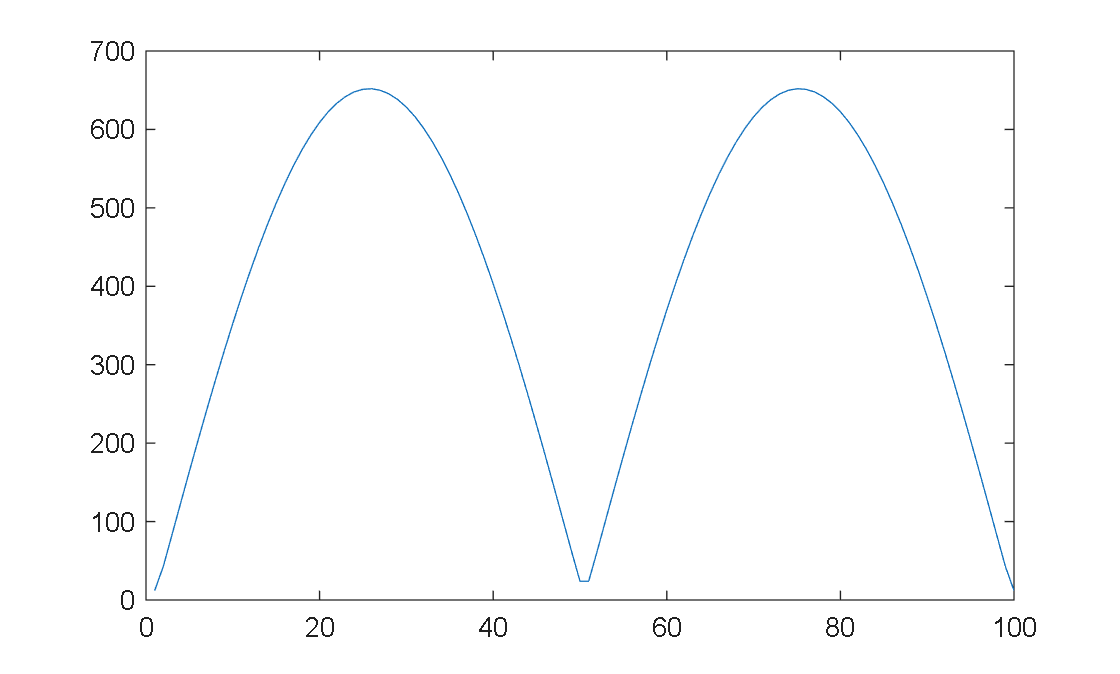

plot(vecnorm(X_0))

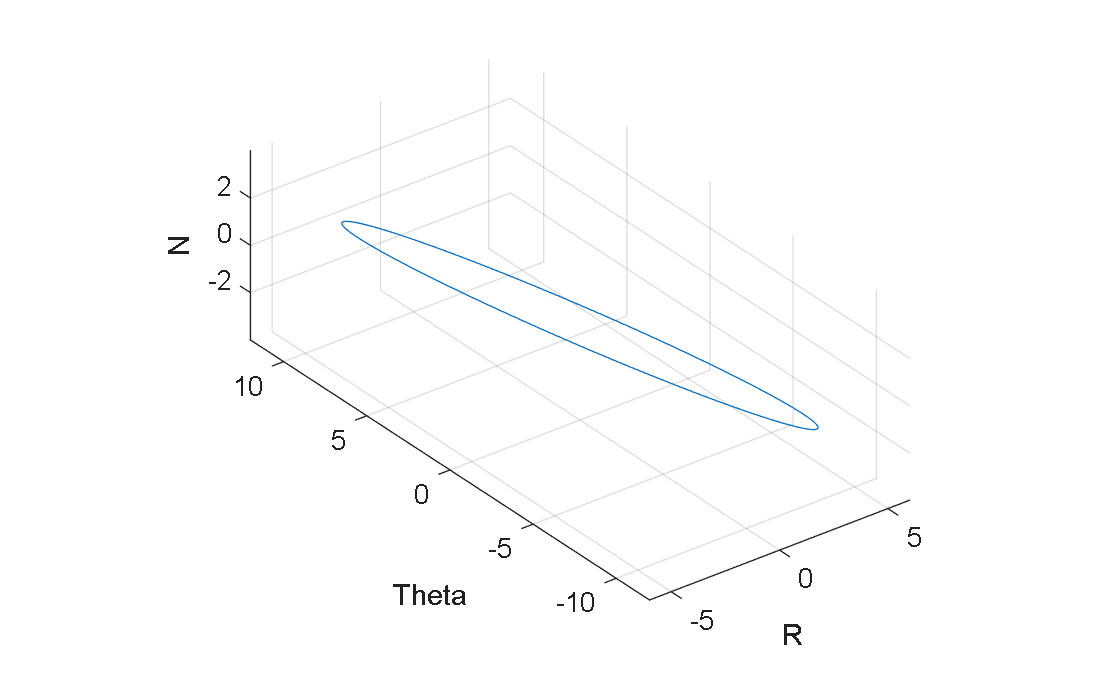

phi = 0.95;
psi = 1.31;
c = 4;
X_0 = [b * sin(nu + phi); 2 * b * cos(nu + phi); c * sin(nu + psi)];
R_E = 6378.137; % [km] Earth radius
mu_E = 398600.4418; % [km3 / s2] Earth gravitational parameter
r_c = 600 + R_E; % [km]
n_c = sqrt(mu_E / r_c ^ 3);
CWH_relative_orbit_EoM()

plot3(X_0(1, :), X_0(2, :), X_0(3, :))
grid on
axis equal
xlabel("R")
ylabel("Theta")
zlabel("N")